# Screening of neural activity deviation

Referring to the paper by Chettih et al. (DOI:[https://doi.org/10.1016/j.cell.2024.02.032](https://doi.org/10.1016/j.cell.2024.02.032)), I will investigate when the neural activity in the MEC and the HPC deviates from baselines in social settings.

## Load data

## Load data

% clear all
% for recID = [3,6,9,12,19]
% for recID = [9,12,19]
for recID = 3:3
% clear all
clearvars -except recID data_all



% Load the table of rec info
ParDir = 'Z:\users\Tatsumi\data\MultiReward'; % parent directory
recListPath = 'H:\My Drive\YartsevLab\Experiment\Multi_reward\Log\Multireward_exp_list_2024.xlsx'; % table of rec info
allRecs = GetRecList(recListPath); % load the rec info list


plot_individual_fr_deviation = false;

% Specify the index of session to be loaded
%% 240207
% recID = 3;
% recID = 4;
% recID = 5;
%% 240208
% recID = 6;
% recID = 7;
% recID = 8;
%% 240209_1
% recID = 9;
% recID = 10;
%% 240209_2
% recID = 11;
%% 240210_1
% recID = 12;
% recID = 13;
%% 240210_2
% recID = 14;
%% 240211_1
% recID = 15;
% recID = 16;
% recID = 17;
%% 240211_2
% recID = 18;
%% 240212
% recID = 19;
% recID = 20;
% recID = 21;


% general information
expType = allRecs.expType{recID}; % experiment type: social/solo/tethered
rewardType = allRecs.rewardType{recID}; % reward type: multi/single flavor
rootdir = fullfile(ParDir,allRecs.rootdir{recID}); % root directory of the recording
ephysDir = fullfile(rootdir,'ephys',allRecs.ephysDir{recID}); % ephys directory
recDate = char(allRecs.date(recID),'MM/dd/yy'); % date of recording
recName = allRecs.recName{recID};
bname_ephys = allRecs.ephysBat{recID}; % name of ephys bat
probeNum = allRecs.probeNum(recID); % probe number
trjName = allRecs.trjName{recID}; % trajectory

cd(rootdir)

% Create output directories
outDir = fullfile(rootdir,'analysis'); % output
figDir = fullfile(rootdir,'analysis','figure'); % figure
if isempty(dir(outDir)); mkdir(outDir); end
if isempty(dir(figDir)); mkdir(figDir); end

% load data
dataTypes = 'barsm'; % data types to be loaded
[BhvData,AnalogData,RewardData,spikeData,mtData] = loadExpData(ParDir, allRecs, recID, dataTypes); % load behavior, analog signals, and reward data
% Landings = extractLandings(BhvData,RewardData,mtData,'include','all');
[Flights, TrjCluster] = extractFlights(BhvData,RewardData,mtData,'include','all');

% Global Figure directory
GbFigDir = 'F:\Data\GroupForaging\Analysis\figure';

### Layer information

Layers = struct([]);

%%% 14633, MEC_2
Layers(1).batid = '14633';
Layers(1).trjName = 'MEC_2'; % name of trajectory

Layers(1).layer(1).name = 'MEC';
Layers(1).layer(1).depth = [0,2800];
Layers(1).layer(1).color = [127,201,127]/255;

Layers(1).layer(2).name = 'VC';
Layers(1).layer(2).depth =[5500,8000];
Layers(1).layer(2).color = [190,174,212]/255;

Layers(1).layer(3).name = 'unknown';
Layers(1).layer(3).depth = [0,0];
Layers(1).layer(3).color = [0,0,0];

%%% 14662, dCA1_MEC_3
Layers(2).batid = '14662'; % id of bat
Layers(2).trjName = 'dCA1_MEC_3'; % name of trajectory
Layers(2).layer(1).name = 'MEC';
Layers(2).layer(1).depth = [0,500];
Layers(2).layer(1).color = [127,201,127]/255;

Layers(2).layer(2).name = 'Subiculum';
Layers(2).layer(2).depth =[500,1600];
Layers(2).layer(2).color = [190,174,212]/255;

Layers(2).layer(3).name = 'DG';
Layers(2).layer(3).depth =[1600,4100];
Layers(2).layer(3).color = [253,192,134]/255;

Layers(2).layer(4).name = 'Subiculum';
Layers(2).layer(4).depth =[4100,5200];
Layers(2).layer(4).color = [190,174,212]/255;

Layers(2).layer(5).name = 'VC';
Layers(2).layer(5).depth =[4100,5200];
Layers(2).layer(5).color = [150,150,150]/255;

Layers(2).layer(6).name = 'unknown';
Layers(2).layer(6).depth = [0,0];
Layers(2).layer(6).color = [0,0,0];


%%% 14662, dCA1_vCA1_3
Layers(3).batid = '14662'; % id of bat
Layers(3).trjName = 'dCA1_vCA1_3'; % name of trajectory

Layers(3).layer(1).name = 'CA1';
Layers(3).layer(1).depth =[0,1700];
Layers(3).layer(1).color = [190,174,212]/255;

Layers(3).layer(2).name = 'CA3';
Layers(3).layer(2).depth = [1700, 3300];
Layers(3).layer(2).color = [253,192,134]/255;

Layers(3).layer(3).name = 'CA1';
Layers(3).layer(3).depth =[3300,4100];
Layers(3).layer(3).color = [190,174,212]/255;

Layers(3).layer(4).name = 'unknown';
Layers(3).layer(4).depth = [0,0];
Layers(3).layer(4).color = [0,0,0];


% Assign region to the spike data structure
unit_ids = spikeData.good_units.cluster_id;
regions = cell(length(unit_ids),1);
for unit = 1:length(unit_ids)
    unit_id = unit_ids(unit);
    depth = spikeData.good_units.depth(unit); % depth of unit
    layers = Layers(strcmp({Layers.trjName},trjName) & strcmp({Layers.batid},bname_ephys)); % specify the layer
    region = get_probe_region(layers,depth);
    regions{unit} = region;
end
spikeData.good_units.region = regions;



### Individual firing rate deviation

#### **Methods in Chettih et al.:**

`To quantify deviations in firing rate, we counted, for each neuron, the number of spikes in a sliding 1 s window.`

`We then computed the probability of observing that spike count in a Poisson process whose rate was equal to the neuron’s average firing rate across the session.`

`We defined firing rate deviation as the negative log of this probability. This value was low whenever the neuron was firing close to its average firing rate; it was high whenever the neuron was firing either above or below its average rate. `

`To compute the population firing rate deviation, we summed values from all neurons and z-scored the result across the session. To measure population firing rate deviation for a specific event (cache, retrieval, check, or visit), we used the 1 s window centered at the offset of the event.`

#### Detect firing deviation for individual MEC neurons

% Ephys bat ID
bb = find(strcmp(bname_ephys,mtData.bname));
% Load behavioral features
t = BhvData.t; % time
fs = BhvData.fs; % frequency for behavioral data
% Parameters
fr_th = 0; % Exclusion criteria for firing rate
w_sz = 1; % sliding window (sec)

% Load neural features
% Target units
target_units =  spikeData.good_units.fr >= fr_th & strcmp(spikeData.good_units.region,'MEC'); % firing rate criteria
% Load data
unit_ids = spikeData.good_units.cluster_id(target_units);
sptimes_all_usec = spikeData.good_units.spikeTimes_usec(target_units); % spike times {# units, }
unit_depths = spikeData.good_units.depth(target_units);
fr = spikeData.good_units.fr(target_units); % firing rate for all units [# units, ]
% n_unit = sum(target_units);

% Exclude the behavioral data after the ephys recording stop
t_ephys_start = min(spikeData.allGlobalSpikeTimes_usec/1e6);
t_ephys_end = max(spikeData.allGlobalSpikeTimes_usec/1e6);

% Compute firing deviation for all units
t_edge = max([ceil(t_ephys_start), 0]):w_sz:min([floor(t_ephys_end),t(end)]);
t_bin = round((t_edge(1:end-1) + t_edge(2:end))/2,1);

% compute fiing deviation
% n_unit = length(sptimes_all_usec)
% deviation = NaN(n_unit,length(t_edge)-1);
% for unit = 1:n_unit
%     sptimes_sec = sptimes_all_usec{unit}/1e6;
% 
%     % Calculate the # of spikes with a sliding window
% 
%     spcounts = histcounts(sptimes_sec,t_edge);
%     deviation(unit,:) = arrayfun(@(x) -log10(poisspdf(x,fr(unit))),spcounts);
% end
deviation = compute_fr_deviation(sptimes_all_usec,fr,t_edge);
deviation_pop = sum(deviation,1);


%%% FIGURE: firing deviation for whole session
% figure
% set(gcf,'unit','normalized','position',[0.1 0.1 0.8 0.8])
% imagesc(deviation,'XData',t_bin,'YData',unit_ids)
% xlabel('Time (sec)')
% ylabel('Unit')

#### Plot firing deviations for individual MEC neurons

if plot_individual_fr_deviation
bb = find(strcmp(bname_ephys,mtData.bname));

r = BhvData.r;
bflying = BhvData.bflying;
n_bats = BhvData.n_tags;
t = BhvData.t;
b_pair = BhvData.bat_pairs;
bname = mtData.bname;

len_fig = 500; % length for 1 figure (sec)
n_fig = ceil(max(t_bin)/len_fig)-floor(min(t_bin)/len_fig);

% Detect reward landings
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');
fd_th = 0.3;

d_fd = NaN(size(r,1),n_bats); % 1 if being on the feeders [t,fd]
for bi = 1:n_bats
    for fd = 1:2
        d_fd(vecnorm(r(:,:,bi)-r_fd(fd,:),2,2)<fd_th,bi) = fd; % feeder 1
    end
end

% Adjacency
th_adj = 0.5; % proximity criteria
oth_bats = [1:bb-1,bb+1:n_bats];
adj = NaN(size(r,1),n_bats-1);
for bi = 1:length(oth_bats)
    adj(:,bi) = adjacency(r(:,:,bb)-r(:,:,oth_bats(bi)),th_adj);
end
adj(adj>0.5) = 1; adj(adj<=0.5) = 0; % 1 if close and 0 otherwise

% normalized deviation
deviation_norm = zscore(deviation,0,2);


for unit = 1:n_unit
% for unit = 1:1
    for fi = 1:n_fig
        idx_fig1 = t_bin>(fi-1)*len_fig & t_bin<fi*len_fig;
        idx_fig2 = t>=(fi-1)*len_fig & t<=fi*len_fig;

        %%%%% FIGURE
        fig = figure('visible','off');
        % fig = figure;
        set(fig,'unit','normalized','position',[0 0 1 1])
        clear AX
        
        %%% Plot 1: firing deviation
        % subplot(2,1,1)
        AX(1) = subplot('position',[0.1 0.8 0.8 0.15]);
        hold on
        plot(t_bin(idx_fig1),deviation_norm(unit,idx_fig1),'k')
        plot([(fi-1)*len_fig,fi*len_fig],repmat(3,2),'--k');
        hold off
        
        grid on
        grid minor
        title(sprintf('Firing deviation: %s, %s, bat%d, unit%d, %.1fHz', ...
            recName,trjName,bb,unit_ids(unit),fr(unit)),'interpreter','none')
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t_bin(idx_fig1)) max(t_bin(idx_fig1))])
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        ylim([-1,30])
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ylabel(sprintf('Firing \n deviation'))
        
        % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+5], ...
            % [0 0 0.4 0.4],'k','clipping','off')
        % text(max(t_bin(idx_fig1))+10, -1, '10 sec', 'fontsize', 14, 'HorizontalAlignment','center')
        
        % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5], ...
        %     [0 0 3 3],'k','clipping','off')
        text(fi*len_fig+6, 3, '3 std', 'fontsize', 14, 'HorizontalAlignment','center')
    
        %%% Plot 2-3: Self behavioral states
        %%% Plot 2: self flight
        AX(2) = subplot('position',[0.1 0.75 0.8 0.01]);
        
        cmat = bflying(idx_fig2,bb)'; cmat(cmat == 0) = NaN;
    
        h = imagesc(cmat,'XData',t(idx_fig2));
        colormap(AX(2),'gray')

        set(h,'AlphaData',~isnan(cmat))
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        % ylim([1,n_bats])
        yticks(1)
        yticklabels(bname(bb))
        title('Self-flights')
        % ylabel(sprintf('Bat ID'))
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ax.YAxis.TickLabelColor = [0 0 0];

        grid on
        grid minor

        %%% Plot 3: Self feeders
        AX(3) = subplot('position',[0.1 0.7 0.8 0.01]);
        
        cmat = d_fd(idx_fig2,bb)';

        h = imagesc(cmat,'XData',t(idx_fig2));
        C = redblue(256);
        colormap(AX(3),C)

        set(h,'AlphaData',~isnan(cmat))
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        % ylim([1,n_bats])
        yticks(1)
        yticklabels(bname(bb))
        title('Self-feeder landings (Red=Feeder 1, Blue=Feeder 2)')
        % ylabel(sprintf('Bat ID'))
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ax.YAxis.TickLabelColor = [0 0 0];

        grid on
        grid minor

        
        %%% Plot 4-5: Ohters' behavioral state
        %%% Plot 4: Otheres' flights
        % subplot(2,1,2)
        AX(4) = subplot('position',[0.1 0.51 0.8 0.15]);
        
        cmat = bflying(idx_fig2,[1:bb-1,bb+1:n_bats])'; cmat(cmat == 0) = NaN;
        for bi = 1:size(cmat,1)
            cmat(bi,:) = cmat(bi,:) + (bi-1);
        end
    
        h = imagesc(cmat,'XData',t(idx_fig2));
        colormap(AX(4),'hsv')
        set(h,'AlphaData',~isnan(cmat))
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        % ylim([1,n_bats])
        yticks(1:size(cmat,1))
        yticklabels(bname([1:bb-1,bb+1:n_bats]))
        title('Others'' flights')
        % ylabel(sprintf('Bat ID'))
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ax.YAxis.TickLabelColor = [0 0 0];
        grid on
        grid minor

        %%% Plot 5: Others' feeder
        AX(5) = subplot('position',[0.1 0.32 0.8 0.15]);
        
        cmat = d_fd(idx_fig2,[1:bb-1,bb+1:n_bats])';

        h = imagesc(cmat,'XData',t(idx_fig2));
        C = redblue(256);
        colormap(AX(5),C)

        set(h,'AlphaData',~isnan(cmat))
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        % ylim([1,n_bats])
        yticks(1:size(cmat,1))
        yticklabels(bname([1:bb-1,bb+1:n_bats]))
        title('Others'' feeder landings (Red=Feeder 1, Blue=Feeder 2)')
        % ylabel(sprintf('Bat ID'))
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ax.YAxis.TickLabelColor = [0 0 0];

        grid on
        grid minor
        
    
        %%% Plot 6: social proximity
        AX(6) = subplot('position',[0.1 0.13 0.8 0.15]);
        
        cmat = adj(idx_fig2,:)'; cmat(cmat == 0) = NaN;
        for bi = 1:size(cmat,1)
            cmat(bi,:) = cmat(bi,:) + (bi-1);
        end
        
        h = imagesc(cmat,'XData',t(idx_fig2));
        colormap(AX(6),'hsv')
        set(h,'AlphaData',~isnan(cmat))
        set(gca,'XColor','none','YColor','none','FontSize',14)
        % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
        xlim([(fi-1)*len_fig, fi*len_fig])
        yticks(1:n_bats-1)
        yticklabels(bname([1:bb-1,bb+1:n_bats]))
        title('Social adjacency')
        % ylabel(sprintf('Bat ID'))
        ax = get(gca);
        ax.YAxis.Label.Color=[0 0 0];
        ax.YAxis.Label.Visible='on';
        ax.YAxis.TickLabelColor = [0 0 0];

        xlabel('Time')
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];


        grid on
        grid minor


        FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName), ...
            'traces_200s',sprintf('Unit%d.png',unit_ids(unit)));
        if isempty(dir(FigDir)); mkdir(FigDir); end
        % Save
        saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d_%d.png',unit_ids(unit),min(t(idx_fig2)),max(t(idx_fig2)))))

        close(fig)
    end
end

end

### Population firing deviation

bb = find(strcmp(bname_ephys,mtData.bname));

r = BhvData.r;
bflying = BhvData.bflying;
n_bats = BhvData.n_tags;
t = BhvData.t;
b_pair = BhvData.bat_pairs;
bname = mtData.bname;

len_fig = 500; % length for 1 figure (sec)
n_fig = ceil(max(t_bin)/len_fig)-floor(min(t_bin)/len_fig);

% Detect reward landings
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');
fd_th = 0.3;

d_fd = NaN(size(r,1),n_bats); % 1 if being on the feeders [t,fd]
for bi = 1:n_bats
    for fd = 1:2
        d_fd(vecnorm(r(:,:,bi)-r_fd(fd,:),2,2)<fd_th,bi) = fd; % feeder 1
    end
end

% Adjacency
th_adj = 0.5; % proximity criteria
oth_bats = [1:bb-1,bb+1:n_bats];
adj = NaN(size(r,1),n_bats-1);
for bi = 1:length(oth_bats)
    adj(:,bi) = adjacency(r(:,:,bb)-r(:,:,oth_bats(bi)),th_adj);
end
adj(adj>0.5) = 1; adj(adj<=0.5) = 0; % 1 if close and 0 otherwise

% normalized deviation
deviation_norm = zscore(deviation_pop);
% deviation_norm = sum(zscore(deviation,0,2),1);

for fi = 1:n_fig
    idx_fig1 = t_bin>(fi-1)*len_fig & t_bin<fi*len_fig;
    idx_fig2 = t>=(fi-1)*len_fig & t<=fi*len_fig;

    %%%%% FIGURE
    fig = figure('visible','off');
    % fig = figure;
    set(fig,'unit','normalized','position',[0 0 1 1])
    clear AX
    
    %%% Plot 1: firing deviation
    % subplot(2,1,1)
    AX(1) = subplot('position',[0.1 0.8 0.8 0.15]);
    hold on
    plot(t_bin(idx_fig1),deviation_norm(idx_fig1),'k')
    plot([(fi-1)*len_fig,fi*len_fig],repmat(3,2),'--k');
    hold off
    
    grid on
    grid minor
    title(sprintf('Population firing deviation: %s, %s, bat%d', ...
        recName,trjName,bb),'interpreter','none')
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t_bin(idx_fig1)) max(t_bin(idx_fig1))])
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    ylim([-1,30])
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ylabel(sprintf('Firing \n deviation'))
    
    % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+5], ...
        % [0 0 0.4 0.4],'k','clipping','off')
    % text(max(t_bin(idx_fig1))+10, -1, '10 sec', 'fontsize', 14, 'HorizontalAlignment','center')
    
    % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5], ...
    %     [0 0 3 3],'k','clipping','off')
    text(fi*len_fig+6, 3, '3 std', 'fontsize', 14, 'HorizontalAlignment','center')

    %%% Plot 2-3: Self behavioral states
    %%% Plot 2: self flight
    AX(2) = subplot('position',[0.1 0.75 0.8 0.01]);
    
    cmat = bflying(idx_fig2,bb)'; cmat(cmat == 0) = NaN;

    h = imagesc(cmat,'XData',t(idx_fig2));
    colormap(AX(2),'gray')

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1)
    yticklabels(bname(bb))
    title('Self-flights')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor

    %%% Plot 3: Self feeders
    AX(3) = subplot('position',[0.1 0.7 0.8 0.01]);
    
    cmat = d_fd(idx_fig2,bb)';

    h = imagesc(cmat,'XData',t(idx_fig2));
    C = redblue(256);
    colormap(AX(3),C)

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1)
    yticklabels(bname(bb))
    title('Self-feeder landings (Red=Feeder 1, Blue=Feeder 2)')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor

    
    %%% Plot 4-5: Ohters' behavioral state
    %%% Plot 4: Otheres' flights
    % subplot(2,1,2)
    AX(4) = subplot('position',[0.1 0.51 0.8 0.15]);
    
    cmat = bflying(idx_fig2,[1:bb-1,bb+1:n_bats])'; cmat(cmat == 0) = NaN;
    for bi = 1:size(cmat,1)
        cmat(bi,:) = cmat(bi,:) + (bi-1);
    end

    h = imagesc(cmat,'XData',t(idx_fig2));
    colors = [0 0 0; 250 0 0; 200 100 0; 
        100 200 0; 0 200 100; 0 250 0; 
        0 0 250; 150 0 150; 100 0 200;
        0 0 0]; 
    colors = colors/255;
    % n_color = max(unique(cmat(~isnan(cmat))));
    colormap(AX(4),colors)
    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1:size(cmat,1))
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Others'' flights')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];
    grid on
    grid minor

    %%% Plot 5: Others' feeder
    AX(5) = subplot('position',[0.1 0.32 0.8 0.15]);
    
    cmat = d_fd(idx_fig2,[1:bb-1,bb+1:n_bats])';

    h = imagesc(cmat,'XData',t(idx_fig2));
    C = redblue(256);
    colormap(AX(5),C)

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1:size(cmat,1))
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Others'' feeder landings (Red=Feeder 1, Blue=Feeder 2)')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor
    

    %%% Plot 6: social proximity
    AX(6) = subplot('position',[0.1 0.13 0.8 0.15]);
    
    cmat = adj(idx_fig2,:)'; cmat(cmat == 0) = NaN;
    for bi = 1:size(cmat,1)
        cmat(bi,:) = cmat(bi,:) + (bi-1);
    end
    
    h = imagesc(cmat,'XData',t(idx_fig2));
    colors = [0 0 0; 250 0 0; 200 100 0; 
        100 200 0; 0 200 100; 0 250 0; 
        0 0 250; 150 0 150; 100 0 200;
        0 0 0];
    colormap(AX(6),C)
    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    yticks(1:n_bats-1)
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Social adjacency')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    xlabel('Time')
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];


    grid on
    grid minor

    FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'traces_200s_population');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    
    % Save
    saveas(fig,fullfile(FigDir,sprintf('Population_firing_%d_%d.png',min(t(idx_fig2)),max(t(idx_fig2)))))
    
    close(fig)
end

The population firing deviation of MEC neurons specifically happens during self-flights. On the other hand, it seems that the population deviation does not match with the others' landings. Also, the other behavioral states such as feeder landings and social proximity does not seem related to the population deviation.

### Cross-correlation of firing deviation between units

Firing rate of neurons deviate during a session, and the timing of deviations are different among neurons. Is there any pair of neurons those that correlate each other in the timings of firing deviation? To find coupled neurons, calculate a cross-correlation for each pair of neurons.

corr_th = 2; % threshold to detect high firing
bin = 1; % bin size (sec)
t_max = 50; % window size (sec)

deviation_norm = zscore(deviation,0,2);
n_unit = size(deviation,1);

% Save directory
FigDir = fullfile(GbFigDir,'Firing_deviation',sprintf('deviation_xcorr_%dstd_allUnits',corr_th), ...
    sprintf('Ephys%s_%s',bname_ephys,trjName), ...
    recName);
if isempty(dir(FigDir)); mkdir(FigDir); end

% Saving structure
if isempty(dir(fullfile(FigDir,'xcorr_deviation.mat')))
    xcorr_deviation = cell(nchoosek(n_unit,2),8); % unit1, unit2, fr1, fr2, depth1, depth2, t peak, coupled
    labels = {'unit1', 'unit2', 'fr1', 'fr2', 'depth1', 'depth2', 't_peak', 't_trough','coupled'};
else
    load(fullfile(FigDir,'xcorr_deviation.mat'))
end

unit_pair = nchoosek(1:n_unit,2);
for pair = 1:length(unit_pair)
    unit1 = unit_pair(pair,1); unit2 = unit_pair(pair,2);
    % spike1 = t_bin(deviation_norm(unit1,:)>corr_th); % sec
    % spike2 = t_bin(deviation_norm(unit2,:)>corr_th); % sec
    % 
    % 
    % [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    % % if unit1 == unit2
    % %     xcc(t_max/bin+5+1) = 0; % auto-correlation
    % % end
    % xcc = xcc(5/bin+1:end-5/bin);
    % xcc = xcc / max(xcc); % Normalize
    % t_xcc = t_xcc(5/bin+1:end-5/bin);
    % 
    % % Detect significant coupling
    % is_peak = xcc > mean(xcc)+3*std(xcc) & t_xcc<=10 & t_xcc >= -10; % < 0.3%
    % 
    % %%% FIGURE
    % fig = figure('visible','off');
    % % fig = figure;
    % xcc_peak = xcc; xcc_peak(~is_peak) = NaN;
    % xcc_npeak = xcc; xcc_npeak(is_peak) = NaN;
    % hold on
    % bar(t_xcc, xcc_npeak,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    % bar(t_xcc, xcc_peak,1,'FaceColor',[250 0 0]/255,'EdgeColor','none','FaceAlpha',0.6)
    % hold off
    % tlt_str = sprintf('Unit%d: %dum, %.1fHz \n Unit%d: %dum, %.1fHz', ...
    %     unit_ids(unit1),unit_depths(unit1),fr(unit1), ...
    %     unit_ids(unit2),unit_depths(unit2),fr(unit2));
    % title(tlt_str)
    % xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    % ylim([0 1.2])
    % % yticks([])
    % set(gca,'XColor','none','YColor','none','FontSize',14)
    % ax = get(gca);
    % ax.XAxis.Label.Color=[0 0 0];
    % ax.XAxis.Label.Visible='on';
    % ax.XAxis.TickLabelColor = [0 0 0];

    % firing deviation timings
    spike1 = t_bin(deviation_norm(unit1,:)>corr_th); % sec
    spike2 = t_bin(deviation_norm(unit2,:)>corr_th); % sec
    n_sp = length(spike2); % # of spikes
    a = -5; b = 5; % min and max of jitter (s)
    
    % Identify firing coupling
    n_ite = 1000; % # of iteration
    xcc = NaN(n_ite+1,(t_max+5)/bin*2+1); % [true+perm, t]
    for i = 1:n_ite+1
        if i == 1 % no shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        else
            jitters = (b-a) .* rand(1,n_sp) + a; % generate random shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2+jitters,bin,t_max+5);
        end
    end
    if unit1 == unit2
        xcc(t_max/bin+5+1) = 0; % auto-correlation
    end
    xcc = xcc(:,5/bin+1:end-5/bin);
    t_xcc = t_xcc(5/bin+1:end-5/bin);
    
    % normalize xcc
    % xcc = xcc / max(xcc(1,:));
    
    % significant level
    xcc_sort = sort(xcc(2:end,:),1);
    xcc_lvl = xcc_sort([floor(5e-3*n_ite)+1,n_ite-floor(5e-3*n_ite)],:); % lower and upper 1% significant level
    
    % detect peak and trough
    is_peak = xcc(1,:) > xcc_lvl(2,:) & t_xcc<=10 & t_xcc >= -10;
    is_trough = xcc(1,:) < xcc_lvl(1,:) & t_xcc<=10 & t_xcc >= -10;
    
    %%% FIGURe
    % fig = figure;
    fig = figure('visible','off');
    % xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak|is_trough) = NaN;
    xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak) = NaN;
    xcc_peak = xcc(1,:); xcc_peak(~is_peak) = NaN;
    % xcc_trough = xcc(1,:); xcc_trough(~is_trough) = NaN;
    
    hold on
    bar(t_xcc, xcc_nonsn,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    bar(t_xcc, xcc_peak,1,'FaceColor',[250 0 0]/255,'EdgeColor','none','FaceAlpha',0.6)
    % bar(t_xcc, xcc_trough,1,'FaceColor',[0 0 250]/255,'EdgeColor','none','FaceAlpha',0.6)
    plot(t_xcc,xcc_lvl(1,:),'--r') % lower significant level
    plot(t_xcc,xcc_lvl(2,:),'--r') % upper significant level
    hold off
    
    tlt_str = sprintf('Unit%d: %dum, %.1fHz \n Unit%d: %dum, %.1fHz', ...
        unit_ids(unit1),unit_depths(unit1),fr(unit1), ...
        unit_ids(unit2),unit_depths(unit2),fr(unit2));
    title(tlt_str)
    xlabel('Time (sec)')
    xticks([-t_max,0,t_max])
    % ylim([0 1.2])
    set(gca,'XColor','none','YColor','none','FontSize',14)
    ax = get(gca);
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];

    % Scale bar
    % patch([-t_max -t_max+10 -t_max+10 -t_max],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    % text(-t_max+5, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    % text(t_max, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','right')
    
    % FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation', ...
    %     sprintf('Ephys%s_%s',bname_ephys,trjName),sprintf('deviation_xcorr_%dstd_allUnits',corr_th));
    % if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
    pause(0.1)

    %% Save   
    xcorr_deviation{pair,1} = unit_ids(unit1);
    xcorr_deviation{pair,2} = unit_ids(unit2);
    xcorr_deviation{pair,3} = fr(unit1);
    xcorr_deviation{pair,4} = fr(unit2);
    xcorr_deviation{pair,5} = unit_depths(unit1);
    xcorr_deviation{pair,6} = unit_depths(unit2);
    xcorr_deviation{pair,7} = t_xcc(is_peak);
    xcorr_deviation{pair,8} = t_xcc(is_trough);
    % xcorr_deviation{pair,9} = any(is_peak|is_trough);
    xcorr_deviation{pair,9} = any(is_peak);

    save(fullfile(FigDir,'xcorr_deviation'),'xcorr_deviation','labels')
end

end

Loading data from Z:\users\Tatsumi\data\MultiReward\multibat\240207 ...
Loading analog signals ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading behavioral data ...
Extracted data are found in the directory.
Behavior data are found in the directory.
Analog signal data are found.
Loading reward data ...
Final MinPeakDistance was 0.5 
322 peaks were detected. 
1 artifacts were detected. It matches with the number of sessions. 
All rewarding landings were recorded and detected.


Loading spike data ...
Kilosort outputs found
Manual curation found
Loading meta data ...


### Cross-correlation for firing deviation during non-flight events

corr_th = 2; % threshold to detect high firing
bin = 1; % bin size (sec)
t_max = 50; % window size (sec)

bflying = BhvData.bflying;

% Population deviation
deviation_pop = sum(deviation,1); % population deviation
deviation_norm = zscore(deviation_pop);
n_unit = size(deviation,1);

[~,loc_peak] = findpeaks(deviation_norm,'MinPeakHeight',corr_th);
t_peak = t_bin(loc_peak);
[~,loc_peak2] = ismember(round(t_peak,2),t);
is_flying = bflying(loc_peak2,bb); is_flying = is_flying == 1;

% Save directory
FigDir = fullfile(GbFigDir,'Firing_deviation',sprintf('deviation_xcorr_%dstd_Fly_vs_NotFly',corr_th), ...
    sprintf('Ephys%s_%s',bname_ephys,trjName), ...
    recName);
if isempty(dir(FigDir)); mkdir(FigDir); end

deviation_norm = zscore(deviation,0,2);
unit_pair = nchoosek(1:n_unit,2);
for pair = 1:length(unit_pair)
    unit1 = unit_pair(pair,1); unit2 = unit_pair(pair,2);

    % Initialize figure
    fig = figure('visible','off');
    set(fig,'unit','normalize','position',[0.3 0.3 0.4 0.3])
    tl = tiledlayout(1,2,'TileSpacing','tight');
    title(tl,sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))

    %% Fly
    spike1 = t_bin(deviation_norm(unit1,is_flying)>corr_th); % sec
    spike2 = t_bin(deviation_norm(unit2,is_flying)>corr_th); % sec
    n_sp = length(spike2); % # of spikes
    a = -5; b = 5; % min and max of jitter (s)
    
    % Identify firing coupling
    n_ite = 1000; % # of iteration
    xcc = NaN(n_ite+1,(t_max+5)/bin*2+1); % [true+perm, t]
    for i = 1:n_ite+1
        if i == 1 % no shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        else
            jitters = (b-a) .* rand(1,n_sp) + a; % generate random shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2+jitters,bin,t_max+5);
        end
    end

    xcc = xcc(:,5/bin+1:end-5/bin);
    t_xcc = t_xcc(5/bin+1:end-5/bin);
    
    % significant level
    xcc_sort = sort(xcc(2:end,:),1);
    xcc_lvl = xcc_sort([floor(5e-3*n_ite)+1,n_ite-floor(5e-3*n_ite)],:); % lower and upper 1% significant level
    
    % detect peak and trough
    is_peak = xcc(1,:) > xcc_lvl(2,:) & t_xcc<=10 & t_xcc >= -10;
    is_trough = xcc(1,:) < xcc_lvl(1,:) & t_xcc<=10 & t_xcc >= -10;
    
    %%% FIGURE
    xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak) = NaN;
    xcc_peak = xcc(1,:); xcc_peak(~is_peak) = NaN;
    
    nexttile
    hold on
    bar(t_xcc, xcc_nonsn,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    bar(t_xcc, xcc_peak,1,'FaceColor',[250 0 0]/255,'EdgeColor','none','FaceAlpha',0.6)
    plot(t_xcc,xcc_lvl(1,:),'--r') % lower significant level
    plot(t_xcc,xcc_lvl(2,:),'--r') % upper significant level
    hold off

    xlabel('Time (sec)')
    xticks([-t_max,0,t_max])
    % ylim([0 1.2])
    set(gca,'XColor','none','YColor','none','FontSize',14)
    ax = get(gca);
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];

    %% Non flight
    spike1 = t_bin(deviation_norm(unit1,~is_flying)>corr_th); % sec
    spike2 = t_bin(deviation_norm(unit2,~is_flying)>corr_th); % sec

    n_sp = length(spike2); % # of spikes
    a = -5; b = 5; % min and max of jitter (s)
    
    % Identify firing coupling
    n_ite = 1000; % # of iteration
    xcc = NaN(n_ite+1,(t_max+5)/bin*2+1); % [true+perm, t]
    for i = 1:n_ite+1
        if i == 1 % no shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        else
            jitters = (b-a) .* rand(1,n_sp) + a; % generate random shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2+jitters,bin,t_max+5);
        end
    end

    xcc = xcc(:,5/bin+1:end-5/bin);
    t_xcc = t_xcc(5/bin+1:end-5/bin);
    
    % significant level
    xcc_sort = sort(xcc(2:end,:),1);
    xcc_lvl = xcc_sort([floor(5e-3*n_ite)+1,n_ite-floor(5e-3*n_ite)],:); % lower and upper 1% significant level
    
    % detect peak and trough
    is_peak = xcc(1,:) > xcc_lvl(2,:) & t_xcc<=10 & t_xcc >= -10;
    is_trough = xcc(1,:) < xcc_lvl(1,:) & t_xcc<=10 & t_xcc >= -10;
    
    %%% FIGURE
    xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak) = NaN;
    xcc_peak = xcc(1,:); xcc_peak(~is_peak) = NaN;
    
    nexttile
    hold on
    bar(t_xcc, xcc_nonsn,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    bar(t_xcc, xcc_peak,1,'FaceColor',[250 0 0]/255,'EdgeColor','none','FaceAlpha',0.6)
    plot(t_xcc,xcc_lvl(1,:),'--r') % lower significant level
    plot(t_xcc,xcc_lvl(2,:),'--r') % upper significant level
    hold off

    xlabel('Time (sec)')
    xticks([-t_max,0,t_max])
    % ylim([0 1.2])
    set(gca,'XColor','none','YColor','none','FontSize',14)
    ax = get(gca);
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];
    
    % Save figure
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

#### Autocorrelation of firing deviation

corr_th = 2; % threshold to detect high firing

deviation_norm = zscore(deviation,0,2);

% Save directory
FigDir = fullfile(GbFigDir,'Firing_deviation',sprintf('deviation_autocorr_%dstd_allUnits',corr_th), ...
    sprintf('Ephys%s_%s',bname_ephys,trjName), ...
    recName);
if isempty(dir(FigDir)); mkdir(FigDir); end

n_unit = size(deviation,1);
for unit1 = 1:n_unit
    spike1 = t_bin(deviation_norm(unit1,:)>corr_th); % sec
    bin = 1; % bin size (sec)
    t_max = 50; % window size (sec)

    [xcc,t_xcc] = crosscorr(spike1,spike1,bin,t_max+5);

    xcc(t_max/bin+5+1) = 0; % exclude the bin for t=0
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    %%% FIGURE
    fig = figure('visible','off');
    % fig = figure;
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    xticks([-t_max,0,t_max])
    ylim([0 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none','FontSize',14)
    ax = get(gca);
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];

    % Scale bar
    % patch([-t_max -t_max+10 -t_max+10 -t_max],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    % text(-t_max+5, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    % text(t_max, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','right')
    % 
    % FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation', ...
    %     sprintf('Ephys%s_%s',bname_ephys,trjName),sprintf('deviation_autocorr_%dstd_allUnits',corr_th));
    % if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d.png',unit_ids(unit1))))
    close(fig)
    pause(0.01)
end

#### Spike cross-correlation

% Parameters
bin = 1; % bin size (msec)
t_max = 25; % window size (msec)

% Saving structure
if isempty(dir(fullfile(FigDir,'xcorr_spike.mat')))
    xcorr_spike = cell(nchoosek(n_unit,2),8); % unit1, unit2, fr1, fr2, depth1, depth2, t peak, coupled
    labels = {'unit1', 'unit2', 'fr1', 'fr2', 'depth1', 'depth2', 't_peak', 't_trough','coupled'};
else
    load(fullfile(FigDir,'xcorr_deviation.mat'))
end

%%% Cross-correlation of all spikes with jittering test
% FigDir = fullfile(GbFigDir,'Spike_Xcorr', ...
%     sprintf('Ephys%s_%s',bname_ephys,trjName), ...
%     recName);
% if isempty(dir(FigDir)); mkdir(FigDir); end

% unit_pair = nchoosek(1:n_unit,2);
% for pair = 1:length(unit_pair)
%     unit1 = unit_pair(pair,1); unit2 = unit_pair(pair,2);
%     if unit1 < unit2
%         spike1 = sptimes_all_usec{unit1}/1e3; % msec
%         spike2 = sptimes_all_usec{unit2}/1e3; % msec
%         n_sp = length(spike2); % # of spikes
%         a = -5; b = 5; % min and max of jitter (s)
% 
%         % Identify firing coupling
%         n_ite = 100; % # of iteration
%         xcc = NaN(n_ite+1,(t_max+5)/bin*2+1); % [true+perm, t]
%         for i = 1:n_ite+1
%             if i == 1 % no shift
%                 [xcc(i,:),t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
%             else
%                 jitters = (b-a) .* rand(n_sp,1) + a; % generate random shift
%                 [xcc(i,:),t_xcc] = crosscorr(spike1,spike2+jitters,bin,t_max+5);
%             end
%         end
% 
%         xcc = xcc(:,5/bin+1:end-5/bin);
%         t_xcc = t_xcc(5/bin+1:end-5/bin);
% 
%         % normalize xcc
%         % xcc = xcc / max(xcc(1,:));
% 
%         % significant level
%         xcc_sort = sort(xcc(2:end,:),1);
%         xcc_lvl = xcc_sort([floor(5e-3*n_ite)+1,n_ite-floor(5e-3*n_ite)],:); % lower and upper 1% significant level
% 
%         % detect peak and trough
%         is_peak = xcc(1,:) > xcc_lvl(2,:) & t_xcc<=10 & t_xcc >= -10;
%         is_trough = xcc(1,:) < xcc_lvl(1,:) & t_xcc<=10 & t_xcc >= -10;
% 
%         %%% FIGURe
%         % fig = figure;
%         fig = figure('visible','off');
%         % xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak|is_trough) = NaN;
%         xcc_nonsn = xcc(1,:); xcc_nonsn(is_peak) = NaN;
%         xcc_peak = xcc(1,:); xcc_peak(~is_peak) = NaN;
%         % xcc_trough = xcc(1,:); xcc_trough(~is_trough) = NaN;
% 
%         hold on
%         bar(t_xcc, xcc_nonsn,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
%         bar(t_xcc, xcc_peak,1,'FaceColor',[250 0 0]/255,'EdgeColor','none','FaceAlpha',0.6)
%         % bar(t_xcc, xcc_trough,1,'FaceColor',[0 0 250]/255,'EdgeColor','none','FaceAlpha',0.6)
%         plot(t_xcc,xcc_lvl(1,:),'--r') % lower significant level
%         plot(t_xcc,xcc_lvl(2,:),'--r') % upper significant level
%         hold off
% 
%         tlt_str = sprintf(['Spike Xcorr \n' ...
%             'Unit%d: %dum, %.1fHz\n' ...
%             'Unit%d: %dum, %.1fHz'], ...
%             unit_ids(unit1),unit_depths(unit1),fr(unit1), ...
%             unit_ids(unit2),unit_depths(unit2),fr(unit2));
%         title(tlt_str)
%         xlabel('Time (sec)')
%         xticks([-t_max,0,t_max])
%         % ylim([0 1.2])
%         set(gca,'XColor','none','YColor','none','FontSize',14)
%         ax = get(gca);
%         ax.XAxis.Label.Color=[0 0 0];
%         ax.XAxis.Label.Visible='on';
%         ax.XAxis.TickLabelColor = [0 0 0];
% 
%         % Scale bar
%         % patch([-t_max -t_max+10 -t_max+10 -t_max],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
%         % text(-t_max+5, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
%         % text(t_max, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','right')
% 
%         % FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation', ...
%         %     sprintf('Ephys%s_%s',bname_ephys,trjName),sprintf('deviation_xcorr_%dstd_allUnits',corr_th));
%         % if isempty(dir(FigDir)); mkdir(FigDir); end
%         saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
%         close(fig)
%         pause(0.1)
% 
%         %% Save   
%         xcorr_spike{pair,1} = unit_ids(unit1);
%         xcorr_spike{pair,2} = unit_ids(unit2);
%         xcorr_spike{pair,3} = fr(unit1);
%         xcorr_spike{pair,4} = fr(unit2);
%         xcorr_spike{pair,5} = unit_depths(unit1);
%         xcorr_spike{pair,6} = unit_depths(unit2);
%         xcorr_spike{pair,7} = t_xcc(is_peak);
%         xcorr_spike{pair,8} = t_xcc(is_trough);
%         % xcorr_deviation{pair,9} = any(is_peak|is_trough);
%         xcorr_spike{pair,9} = any(is_peak);
% 
%         save(fullfile(FigDir,'xcorr_spike'),'xcorr_spikes','labels')
%     end
% end

%%% Cross-correlation of all spikes without jittering test
% Save dir
FigDir = fullfile(GbFigDir,'Spike_Xcorr_No_jitterTest', ...
    sprintf('Ephys%s_%s',bname_ephys,trjName), ...
    recName);
if isempty(dir(FigDir)); mkdir(FigDir); end

% Compute and plot cross-correlogram
unit_pair = nchoosek(1:n_unit,2);
for pair = 1:length(unit_pair)
    unit1 = unit_pair(pair,1); unit2 = unit_pair(pair,2);
    if unit1 < unit2
        spike1 = sptimes_all_usec{unit1}/1e3; % msec
        spike2 = sptimes_all_usec{unit2}/1e3; % msec

    n_sp = length(spike2); % # of spikes
    a = -5; b = 5; % min and max of jitter (s)
    
    % Identify firing coupling
    n_ite = 1000; % # of iteration
    xcc = NaN(n_ite+1,(t_max+5)/bin*2+1); % [true+perm, t]
    for i = 1:n_ite+1
        if i == 1 % no shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        else
            jitters = (b-a) .* rand(1,n_sp) + a; % generate random shift
            [xcc(i,:),t_xcc] = crosscorr(spike1,spike2+jitters,bin,t_max+5);
        end
    end

        [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        xcc = xcc(5/bin+1:end-5/bin);
        xcc = xcc / max(xcc); % Normalize
        t_xcc = t_xcc(5/bin+1:end-5/bin);

        %%% FIGURe
        fig = figure('visible','off');
        % fig = figure;
        bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
        title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
        xlabel('Time (ms)')
        xticks([-t_max,0,t_max])
        ylim([0 1.2])
        % yticks([])
        set(gca,'XColor','none','YColor','none','FontSize',14)
        ax = get(gca);
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];

        saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
        close(fig)
        pause(0.1)

    end
end

## Analysis for socially modulated neurons

Socially modulated neurons were identified based on c-test (p<0.001), GLM (p<0.01), and visual inspection.

## Population firing deviation for socially modulated neurons

bb = find(strcmp(bname_ephys,mtData.bname));

r = BhvData.r;
bflying = BhvData.bflying;
n_bats = BhvData.n_tags;
t = BhvData.t;
b_pair = BhvData.bat_pairs;
bname = mtData.bname;

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Social_modulation_240210_1.xlsx';
res_table = readtable(file_path,'VariableNamingRule','preserve');
self_land = res_table.self_land;
self_toff = res_table.self_toff;
other_land = res_table.other_land;
other_toff = res_table.other_toff;
action_social = [self_land, self_toff, other_land, other_toff];
% action_social = [other_land, other_toff];
% action_social = [1-self_land, 1-self_toff, other_land, other_toff];
action_social = action_social == 1;
% is_social_neuron = any(action_social,2);
is_social_neuron = ~any(action_social(:,1:2),2) & any(action_social(:,3:4),2);
n_social_neuron = sum(is_social_neuron);

len_fig = 500; % length for 1 figure (sec)
n_fig = ceil(max(t_bin)/len_fig)-floor(min(t_bin)/len_fig);

% Detect reward landings
% r_fd = [2.77,0.82,1.75; 2.79,-0.99,1.64; 2.78,1.29,0.84; 2.78,-1.43,0.80]; % Feeder position
[r_fd,~] = r_feeder_calibrate('Y:\users\Tatsumi\Data\Flight_room_test\240120_feeder_calibration');
fd_th = 0.3;

d_fd = NaN(size(r,1),n_bats); % 1 if being on the feeders [t,fd]
for bi = 1:n_bats
    for fd = 1:2
        d_fd(vecnorm(r(:,:,bi)-r_fd(fd,:),2,2)<fd_th,bi) = fd; % feeder 1
    end
end

% Adjacency
th_adj = 0.5; % proximity criteria
oth_bats = [1:bb-1,bb+1:n_bats];
adj = NaN(size(r,1),n_bats-1);
for bi = 1:length(oth_bats)
    adj(:,bi) = adjacency(r(:,:,bb)-r(:,:,oth_bats(bi)),th_adj);
end
adj(adj>0.5) = 1; adj(adj<=0.5) = 0; % 1 if close and 0 otherwise

% normalized deviation
deviation_pop = sum(deviation(is_social_neuron,:),1);
deviation_norm = zscore(deviation_pop);
% deviation_norm = sum(zscore(deviation,0,2),1);

for fi = 1:n_fig
    idx_fig1 = t_bin>(fi-1)*len_fig & t_bin<fi*len_fig;
    idx_fig2 = t>=(fi-1)*len_fig & t<=fi*len_fig;

    %%%%% FIGURE
    fig = figure('visible','off');
    % fig = figure;
    set(fig,'unit','normalized','position',[0 0 1 1])
    clear AX
    
    %%% Plot 1: firing deviation
    % subplot(2,1,1)
    AX(1) = subplot('position',[0.1 0.8 0.8 0.15]);
    hold on
    plot(t_bin(idx_fig1),deviation_norm(idx_fig1),'k')
    plot([(fi-1)*len_fig,fi*len_fig],repmat(3,2),'--k');
    hold off
    
    grid on
    grid minor
    title(sprintf('Population firing deviation: %s, %s, bat%d', ...
        recName,trjName,bb),'interpreter','none')
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t_bin(idx_fig1)) max(t_bin(idx_fig1))])
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    ylim([-1,30])
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ylabel(sprintf('Firing \n deviation'))
    
    % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+15 max(t_bin(idx_fig1))+5], ...
        % [0 0 0.4 0.4],'k','clipping','off')
    % text(max(t_bin(idx_fig1))+10, -1, '10 sec', 'fontsize', 14, 'HorizontalAlignment','center')
    
    % patch([max(t_bin(idx_fig1))+5 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5.4 max(t_bin(idx_fig1))+5], ...
    %     [0 0 3 3],'k','clipping','off')
    text(fi*len_fig+6, 3, '3 std', 'fontsize', 14, 'HorizontalAlignment','center')

    %%% Plot 2-3: Self behavioral states
    %%% Plot 2: self flight
    AX(2) = subplot('position',[0.1 0.75 0.8 0.01]);
    
    cmat = bflying(idx_fig2,bb)'; cmat(cmat == 0) = NaN;

    h = imagesc(cmat,'XData',t(idx_fig2));
    colormap(AX(2),'gray')

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1)
    yticklabels(bname(bb))
    title('Self-flights')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor

    %%% Plot 3: Self feeders
    AX(3) = subplot('position',[0.1 0.7 0.8 0.01]);
    
    cmat = d_fd(idx_fig2,bb)';

    h = imagesc(cmat,'XData',t(idx_fig2));
    C = redblue(256);
    colormap(AX(3),C)

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1)
    yticklabels(bname(bb))
    title('Self-feeder landings (Red=Feeder 1, Blue=Feeder 2)')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor

    
    %%% Plot 4-5: Ohters' behavioral state
    %%% Plot 4: Otheres' flights
    % subplot(2,1,2)
    AX(4) = subplot('position',[0.1 0.51 0.8 0.15]);
    
    cmat = bflying(idx_fig2,[1:bb-1,bb+1:n_bats])'; cmat(cmat == 0) = NaN;
    for bi = 1:size(cmat,1)
        cmat(bi,:) = cmat(bi,:) + (bi-1);
    end

    h = imagesc(cmat,'XData',t(idx_fig2));
    colormap(AX(4),'hsv')
    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1:size(cmat,1))
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Others'' flights')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];
    grid on
    grid minor

    %%% Plot 5: Others' feeder
    AX(5) = subplot('position',[0.1 0.32 0.8 0.15]);
    
    cmat = d_fd(idx_fig2,[1:bb-1,bb+1:n_bats])';

    h = imagesc(cmat,'XData',t(idx_fig2));
    C = redblue(256);
    colormap(AX(5),C)

    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    % ylim([1,n_bats])
    yticks(1:size(cmat,1))
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Others'' feeder landings (Red=Feeder 1, Blue=Feeder 2)')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    grid on
    grid minor
    

    %%% Plot 6: social proximity
    AX(6) = subplot('position',[0.1 0.13 0.8 0.15]);
    
    cmat = adj(idx_fig2,:)'; cmat(cmat == 0) = NaN;
    for bi = 1:size(cmat,1)
        cmat(bi,:) = cmat(bi,:) + (bi-1);
    end
    
    h = imagesc(cmat,'XData',t(idx_fig2));
    colormap(AX(6),'hsv')
    set(h,'AlphaData',~isnan(cmat))
    set(gca,'XColor','none','YColor','none','FontSize',14)
    % xlim([min(t(idx_fig2)) max(t(idx_fig2))])
    xlim([(fi-1)*len_fig, fi*len_fig])
    yticks(1:n_bats-1)
    yticklabels(bname([1:bb-1,bb+1:n_bats]))
    title('Social adjacency')
    % ylabel(sprintf('Bat ID'))
    ax = get(gca);
    ax.YAxis.Label.Color=[0 0 0];
    ax.YAxis.Label.Visible='on';
    ax.YAxis.TickLabelColor = [0 0 0];

    xlabel('Time')
    ax.XAxis.Label.Color=[0 0 0];
    ax.XAxis.Label.Visible='on';
    ax.XAxis.TickLabelColor = [0 0 0];


    grid on
    grid minor

    FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'traces_200s_population_social');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    
    % Save
    saveas(fig,fullfile(FigDir,sprintf('Social_population_firing_%d_%d.png',min(t(idx_fig2)),max(t(idx_fig2)))))
    
    close(fig)
end

### Firing deviation during self-flights

%%% Self-landing
t_fly_sec = Flights(bb).t_flight_sec;
% t_flight = Flights(bb).t_flight;
n_flight = Flights(bb).n_flight;

deviation_norm = zscore(deviation,0,2);

fr_flights = NaN(n_flight,n_unit);
for unit = 1:n_unit 
    
    for fl = 1:n_flight
        % sptimes = sptimes_all_usec{unit}/1e6;
        % fr_flights(fl) = sum(sptimes > t_fly_sec(fl,1) & sptimes < t_fly_sec(fl,2)) / diff(t_fly_sec(fl,:));
        idx = t_bin>t_fly_sec(fl,1) & t_bin<t_fly_sec(fl,2);
        fr_flights(fl,unit) = mean(deviation_norm(unit,idx));
    end
    fr_flights(fr_flights(:,unit)<0,unit) = 0;
    fr_flights(fr_flights(:,unit)>10,unit) = 10;
    
    fig = figure('visible','off');
    set(fig,'unit','normalize','position',[0.3 0.3 0.3 0.3])
    scatter(1:n_flight,fr_flights(:,unit),'ok')
    
    hold on
    for fl = 1:n_flight
        line([fl fl], [0 max([fr_flights(fl,unit),0])],'Color','k')
    end
    plot([1,n_flight],repmat(2,2),'--k');
    hold off
    title(sprintf('Unit%d, %.1fHz',unit_ids(unit),frs(unit)))
    ylabel('Firing deviation')
    xlabel('Flight #')
    xlim([1,n_flight])
    ylim([0,10])
    yticks([0,10])
    yticklabels({'<=0','>=10'})
    
    set(gca,'TickDir','none','FontSize',14)

    text(n_flight+4, 2, '2 std', 'fontsize', 14, 'HorizontalAlignment','center')
     
    % Save
    FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'Flight_deviation_units','self_takeoff');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d.png',unit_ids(unit))))
    
    close(fig)  
end


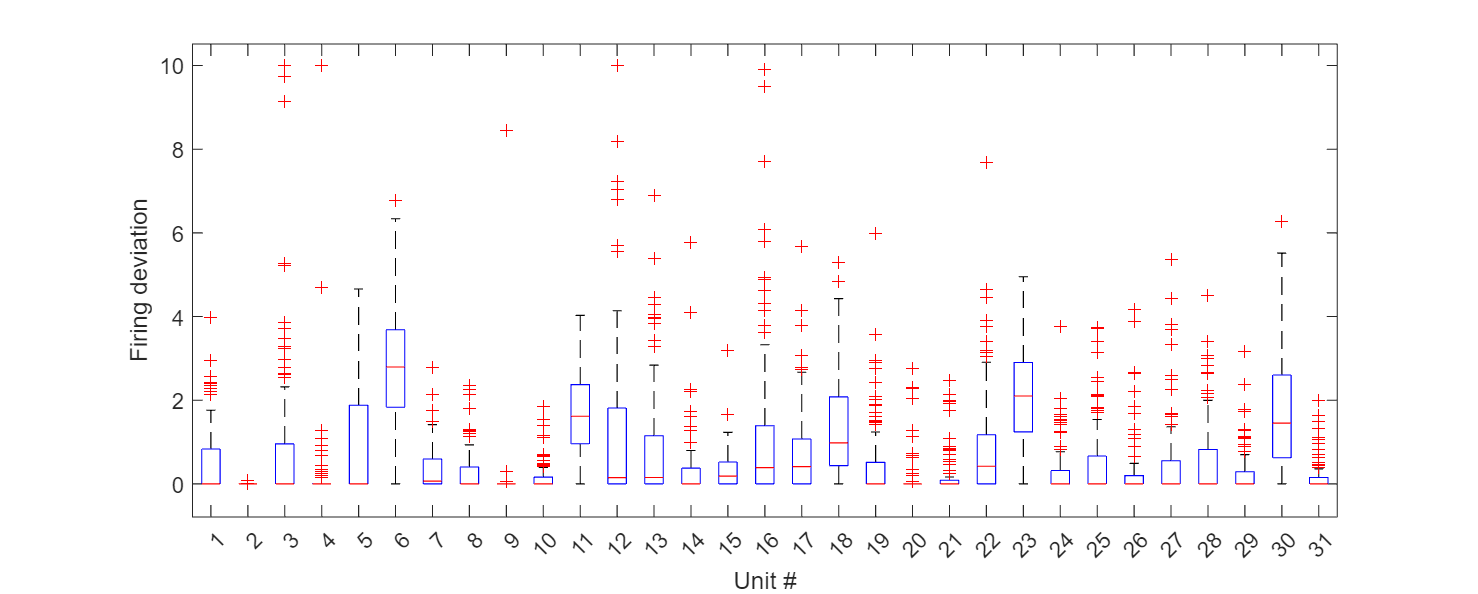


% x = repmat(1:n_unit,[n_flight,1]);
% x = x(:)';
% y = fr_flights(:)';

fig = figure;
set(fig,'unit','normalized','position',[0 0.3 0.35 0.25])
boxplot(fr_flights)   
% swarmchart(x,y,'filled','ok','MarkerFaceAlpha',0.3,'XJitterWidth',1)
xlabel('Unit #')
ylabel('Firing deviation')

% Save
FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'Flight_deviation_units');
if isempty(dir(FigDir)); mkdir(FigDir); end
saveas(fig,fullfile(FigDir,'Firing_deviation_distribution.png'))


close(fig) 

% 
% %%% Self-takeoff
% t_fly_sec = Flights(bb).t_land_sec;
% % t_flight = Flights(bb).t_flight;
% n_flight = Flights(bb).n_flight;
% 
% deviation_norm = zscore(deviation,0,2);
% 
% for unit = 1:n_unit 
%     fr_flights = NaN(n_flight,1);
%     for fl = 1:n_flight
%         % sptimes = sptimes_all_usec{unit}/1e6;
%         % fr_flights(fl) = sum(sptimes > t_fly_sec(fl,1) & sptimes < t_fly_sec(fl,2)) / diff(t_fly_sec(fl,:));
%         idx = t_bin>t_fly_sec(fl,1) & t_bin<t_fly_sec(fl,2);
%         fr_flights(fl) = mean(deviation_norm(unit,idx))
%     end
% 
%     fig = figure('visible','off');
%     set(fig,'unit','normalize','position',[0.3 0.3 0.5 0.3])
%     scatter(1:n_flight,fr_flights,'ok')
%     hold on
%     for fl = 1:n_flight
%         line([fl fl], [0 fr_flights(fl)],'Color','k')
%     end
%     hold off
%     title(sprintf('Unit%d, %.1fHz',unit_ids(unit),frs(unit)))
%     ylabel('Firing rate (Hz)')
%     xlabel('Landing #')
%     xlim([1,n_flight])
%     set(gca,'TickDir','none','FontSize',14)
% 
%     % Save
%     FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'Flight_deviation_units','self_landing');
%     if isempty(dir(FigDir)); mkdir(FigDir); end
%     saveas(fig,fullfile(FigDir,sprintf('Unit%d.png',unit_ids(unit))))
% 
%     close(fig)  
% end

### Cross-correlation of firing deviation between units

Firing rate of neurons deviate during a session, and the timing of deviations are different among neurons. Is there any pair of neurons those that correlate each other in the timings of firing deviation? To find coupled neurons, calculate a cross-correlation for each pair of neurons.

corr_th = 2; % threshold to detect high firing

deviation_norm = zscore(deviation,0,2);
for unit1 = 1:n_unit
% for unit1 = 6:6
    for unit2 = 1:n_unit
        spike1 = t_bin(deviation_norm(unit1,:)>corr_th); % sec
        spike2 = t_bin(deviation_norm(unit2,:)>corr_th); % sec
        bin = 1; % bin size (sec)
        t_max = 50; % window size (sec)

        [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        if unit1 == unit2
            xcc(t_max/bin+5+1) = 0; % auto-correlation
        end
        xcc = xcc(5/bin+1:end-5/bin);
        xcc = xcc / max(xcc); % Normalize
        t_xcc = t_xcc(5/bin+1:end-5/bin);

        fig = figure('visible','off');
        % fig = figure;
        bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
        title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
        xlabel('Time (sec)')
        xticks([-t_max,0,t_max])
        ylim([0 1.2])
        % yticks([])
        set(gca,'XColor','none','YColor','none','FontSize',14)
        ax = get(gca);
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];

        % Scale bar
        % patch([-t_max -t_max+10 -t_max+10 -t_max],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
        % text(-t_max+5, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
        % text(t_max, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','right')
    
        FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation', ...
            sprintf('Ephys%s_%s',bname_ephys,trjName),'deviation_xcorr_HighDev_allUnits');
        if isempty(dir(FigDir)); mkdir(FigDir); end
        saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
        close(fig)
    end
end

#### Result of visual inspection

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Firing_deviation_coupled_units.xlsx';
res_table = readtable(file_path,'VariableNamingRule','preserve');

unit1 = res_table.Unit1;
unit2 = res_table.Unit2;
coupled_units = unique([unit1;unit2]);

#### Spike cross-correlation

% Cross-correlation of all spikes
for unit1 = 1:n_unit
    for unit2 = 1:n_unit
        spike1 = sptimes_all_usec{unit1}/1e3; % msec
        spike2 = sptimes_all_usec{unit2}/1e3; % msec
        bin = 1; % bin size (msec)
        t_max = 25; % window size (msec)
    
        [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        xcc = xcc(5/bin+1:end-5/bin);
        if unit1 == unit2
            xcc(t_max/bin+1) = 0;
        end
        xcc = xcc / max(xcc); % Normalize
        t_xcc = t_xcc(5/bin+1:end-5/bin);

        fig = figure('visible','off');
        % fig = figure;
        bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
        title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
        xlabel('Time (ms)')
        xticks([-t_max,0,t_max])
        ylim([0 1.2])
        % yticks([])
        set(gca,'XColor','none','YColor','none','FontSize',14)
        ax = get(gca);
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];
    
        FigDir = fullfile(rootdir,'analysis','figure','Spike_Xcorr', ...
            sprintf('Ephys%s_%s',bname_ephys,trjName));
        if isempty(dir(FigDir)); mkdir(FigDir); end
        saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
        close(fig)
    end
end

#### Result of visual inspection

% file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Firing_deviation_coupled_units.xlsx';
% res_table = readtable(file_path,'VariableNamingRule','preserve');
% 
% dual_xcorr = res_table.spike_corr;
% num_dual_xcorr = sum(dual_xcorr)

num_dual_xcorr = 22

### GLM for firing deviation

% th_social = 0.5;
% t_fly_sec = Flights(bb).t_flight_sec;
% n_flight = Flights(bb).n_flight;
% is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight
% r_x = Flights(bb).r_land_median(:,1);
% r_y = Flights(bb).r_land_median(:,2);
% 
% dev_flights = NaN(n_flight,n_unit);
% 
% unit = 10;
%     for fl = 1:n_flight
%         % sptimes = sptimes_all_usec{unit}/1e6;
%         % fr_flights(fl) = sum(sptimes > t_fly_sec(fl,1) & sptimes < t_fly_sec(fl,2)) / diff(t_fly_sec(fl,:));
%         idx = t_bin>t_fly_sec(fl,1) & t_bin<t_fly_sec(fl,2);
%         dev_flights(fl,unit) = mean(deviation(unit,idx));
%     end
% 
%     r_x = r_x(~isnan(dev_flights(:,unit)));
%     r_y = r_y(~isnan(dev_flights(:,unit)));
%     is_social = is_social(~isnan(dev_flights(:,unit)));
%     dev = dev_flights(~isnan(dev_flights(:,unit)),unit);
% 
%     T_vars = table(r_x,r_y,is_social,dev);
%     mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');

1. Adding r_x, Deviance = 64.0629, Chi2Stat = 9.94087, PValue = 0.00161649




%%% Self-landing
t_fly_sec = Flights(bb).t_flight_sec;
% t_flight = Flights(bb).t_flight;
n_flight = Flights(bb).n_flight;

th_social = 0.5;
is_social = Flights(bb).closest_oth_dist < th_social; % true if social flight
r_x = Flights(bb).r_land_median(:,1);
r_y = Flights(bb).r_land_median(:,2);

% deviation_norm = zscore(deviation,0,2);

dev_flights = NaN(n_flight,n_unit);
for unit = 1:n_unit 
    
    for fl = 1:n_flight
        % sptimes = sptimes_all_usec{unit}/1e6;
        % fr_flights(fl) = sum(sptimes > t_fly_sec(fl,1) & sptimes < t_fly_sec(fl,2)) / diff(t_fly_sec(fl,:));
        idx = t_bin>t_fly_sec(fl,1) & t_bin<t_fly_sec(fl,2);
        dev_flights(fl,unit) = mean(deviation(unit,idx));
    end

    is_include = ~isnan(dev_flights(:,unit));

    dev_fig = zscore(dev_flights(is_include,unit));
    dev_fig(dev_fig<0,unit) = 0;
    dev_fig(dev_fig>10,unit) = 10;

    % GLM
    r_x = r_x(is_include);
    r_y = r_y(is_include);
    is_social = is_social(is_include);
    dev = dev_flights(is_include,unit);

    T_vars = table(r_x,r_y,is_social,dev);
    mdl = stepwiseglm(T_vars,'constant','Distribution','poisson','Link','log');

    coef_names = mdl.CoefficientNames(2:end);
    coef_pvalues = mdl.Coefficients.pValue(2:end);
    coef_sig = coef_names(coef_pvalues < 0.01); % significant coefficients
    coef_sig = join(coef_sig,',');
    
    % FIGURE
    fig = figure('visible','off');
    set(fig,'unit','normalize','position',[0.3 0.3 0.3 0.3])
    scatter(1:sum(is_include),dev_fig,'ok')
    
    hold on
    for fl = 1:sum(is_include)
        line([fl fl], [0 max([dev_fig(fl),0])],'Color','k')
    end
    plot([1,sum(is_include)],repmat(2,2),'--k');
    hold off
    title_str = sprintf('Unit%d, %.1fHz: \nGLM: %s',unit_ids(unit),frs(unit),coef_sig{:});
    title(title_str,'Interpreter','None')
    ylabel('Firing deviation')
    xlabel('Flight #')
    xlim([1,n_flight])
    ylim([0,10])
    yticks([0,10])
    yticklabels({'<=0','>=10'})
    
    set(gca,'TickDir','none','FontSize',14)

    text(n_flight+4, 2, '2 std', 'fontsize', 14, 'HorizontalAlignment','center')
     
    % Save
    FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation',sprintf('Ephys%s_%s',bname_ephys,trjName),'Flight_deviation_GLM','self_takeoff');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d.png',unit_ids(unit))))
    
    close(fig)  
end

1. Adding r_x, Deviance = 101.5883, Chi2Stat = 16.7887, PValue = 4.178136e-05
No terms to add to or remove from initial model.
1. Adding r_y, Deviance = 294.0225, Chi2Stat = 211.5924, PValue = 6.172565e-48
1. Adding r_y, Deviance = 143.0851, Chi2Stat = 30.48402, PValue = 3.366287e-08
2. Adding is_social, Deviance = 137.1763, Chi2Stat = 5.908804, PValue = 0.0150654
3. Adding r_x, Deviance = 132.5609, Chi2Stat = 4.615339, PValue = 0.03168723
4. Adding r_y:is_social, Deviance = 128.2205, Chi2Stat = 4.340441, PValue = 0.03721728
1. Adding r_x, Deviance = 100.2843, Chi2Stat = 110.7955, PValue = 6.560064e-26
2. Adding r_y, Deviance = 77.9366, Chi2Stat = 22.3477, PValue = 2.27488e-06
3. Adding r_x:r_y, Deviance = 69.5775, Chi2Stat = 8.35919, PValue = 0.00383742
1. Adding r_x, Deviance = 324.3397, Chi2Stat = 61.0066, PValue = 5.688376e-15
1. Adding r_x, Deviance = 12.702, Chi2Stat = 5.65624, PValue = 0.0173933
No terms to add to or remove from initial model.
1. Adding r_y, Deviance = 66.4108, 

## Analysis of socially modulated neurons

[240207] Self landings: 20.0% (11/55)


[240207] Self takeoffs: 21.8% (12/55)


[240207] Others' landings: 16.4% (9/55)


[240207] Others' landings: 12.7% (7/55)


[240208] Self landings: 31.7% (13/41)


[240208] Self takeoffs: 12.2% (5/41)


[240208] Others' landings: 36.6% (15/41)


[240208] Others' landings: 31.7% (13/41)


[240209_1] Self landings: 23.8% (10/42)


[240209_1] Self takeoffs: 16.7% (7/42)


[240209_1] Others' landings: 21.4% (9/42)


[240209_1] Others' landings: 11.9% (5/42)


[240210_1] Self landings: 38.7% (12/31)


[240210_1] Self takeoffs: 25.8% (8/31)


[240210_1] Others' landings: 29.0% (9/31)


[240210_1] Others' landings: 9.7% (3/31)


[240212] Self landings: 22.7% (5/22)


[240212] Self takeoffs: 18.2% (4/22)


[240212] Others' landings: 13.6% (3/22)


[240212] Others' landings: 27.3% (6/22)


### Coupling of socially modulated neurons

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Social_modulation_240210_1.xlsx';
res_table = readtable(file_path,'VariableNamingRule','preserve');

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Firing_deviation_coupled_units.xlsx';
res2 = readtable(file_path,'VariableNamingRule','preserve');

self_land = res_table.self_land;
self_toff = res_table.self_toff;
other_land = res_table.other_land;
other_toff = res_table.other_toff;

action_social = [self_land, self_toff, other_land, other_toff];
action_social = action_social == 1;

n_social_neuron = sum(any(action_social,2));
social_neuron = unit_ids(any(action_social,2));

is_social_neuron = ismember(res2.Unit1,social_neuron) & ismember(res2.Unit2,social_neuron);

coupled_social_neuron = unique([res2.Unit1(ismember(res2.Unit1,social_neuron)); res2.Unit2(ismember(res2.Unit2,social_neuron))]);

### Non-flight population deviation

% Extract social neurons
file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Social_modulation_240210_1.xlsx';
res_table = readtable(file_path,'VariableNamingRule','preserve');

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Firing_deviation_coupled_units.xlsx';
res2 = readtable(file_path,'VariableNamingRule','preserve');

self_land = res_table.self_land;
self_toff = res_table.self_toff;
other_land = res_table.other_land;
other_toff = res_table.other_toff;

action_social = [self_land, self_toff, other_land, other_toff];
action_social = action_social == 1;
is_social_neuron = any(action_social,2);
social_neuron = unit_ids(is_social_neuron);

% Population deviation
deviation_pop = sum(deviation,1); % population deviation
deviation_norm = zscore(deviation_pop);

[~,loc_peak] = findpeaks(deviation_norm,'MinPeakHeight',3);
t_peak = t_bin(loc_peak);
[~,loc_peak2] = ismember(round(t_peak,2),t);
t_peak = t(loc_peak2);
is_flying = bflying(loc_peak2,bb); is_flying = is_flying == 1;

deviation_peak = deviation(:,loc_peak);
nonsocial_fly = deviation_peak(~is_social_neuron,is_flying);
social_fly = deviation_peak(is_social_neuron,is_flying);
nonsocial_rest = deviation_peak(~is_social_neuron,~is_flying);
social_rest = deviation_peak(is_social_neuron,~is_flying);

%%% FIGURE
fig = figure('visible','on');

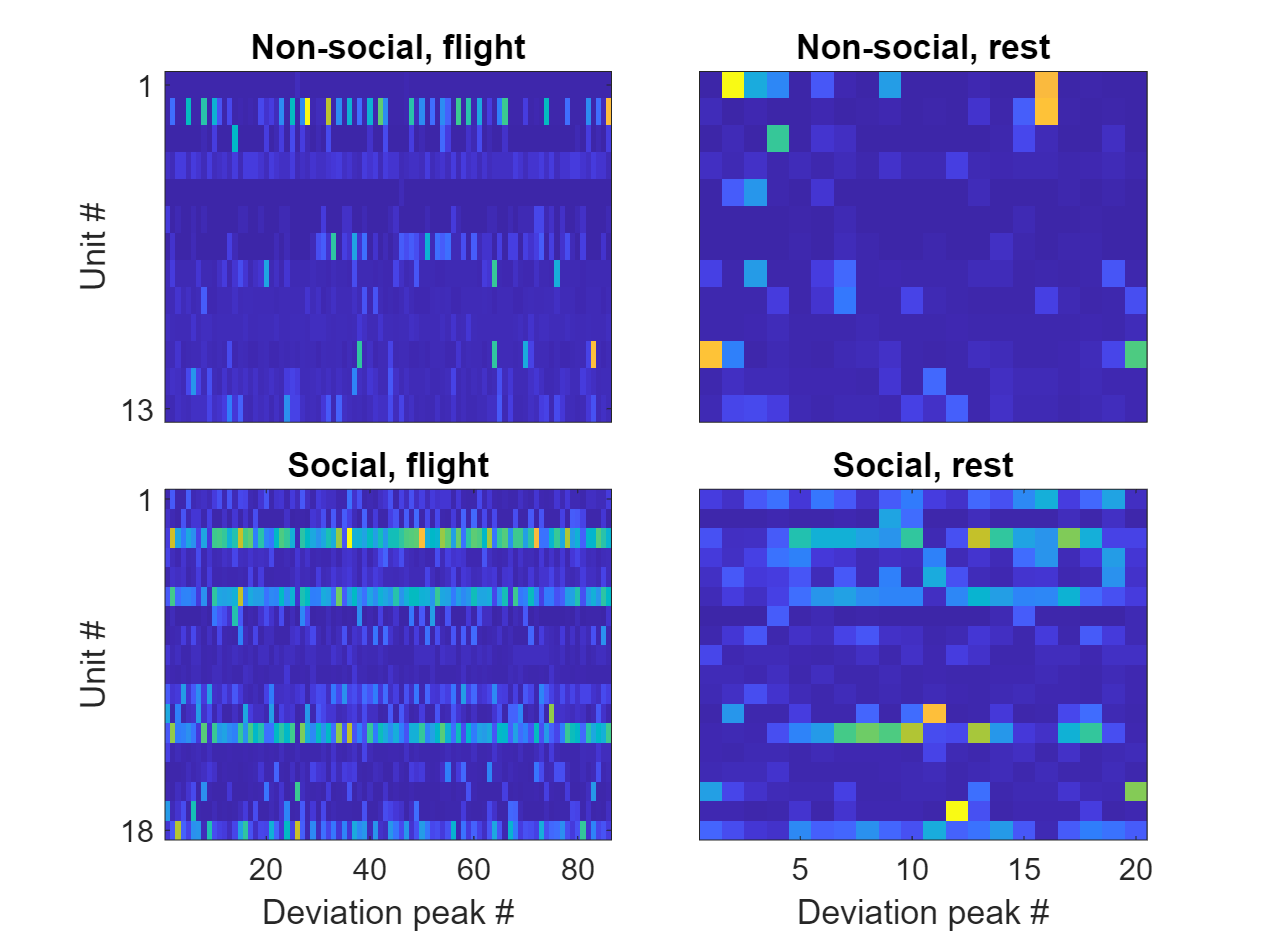

fig = figure;
set(fig,'unit','normalize','position',[0.3 0.3 0.3 0.4])
tl = tiledlayout(2,2,'TileSpacing','compact');

nexttile(1)
imagesc(nonsocial_fly)
title('Non-social, flight')
xticks([])
ylabel('Unit #')
yticks([1,size(nonsocial_fly,1)])
set(gca,'FontSize',14)

nexttile(3)
imagesc(social_fly)
title('Social, flight')
ylabel('Unit #')
yticks([1,size(social_fly,1)])
xlabel('Deviation peak #')
set(gca,'FontSize',14)

nexttile(2)
imagesc(nonsocial_rest)
title('Non-social, rest')
xticks([])
yticks([])
set(gca,'FontSize',14)

nexttile(4)
imagesc(social_rest)
title('Social, rest')
yticks([])
xlabel('Deviation peak #')
set(gca,'FontSize',14)

### Cross-correlation for firing deviation during non-flight events

corr_th = 2; % threshold to detect high firing


% Extract social neurons
file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Social_modulation_240210_1.xlsx';
res_table = readtable(file_path,'VariableNamingRule','preserve');

file_path = 'Z:\users\Tatsumi\data\MultiReward\Analysis\2024_Feb\Firing_deviation_coupled_units.xlsx';
res2 = readtable(file_path,'VariableNamingRule','preserve');

self_land = res_table.self_land;
self_toff = res_table.self_toff;
other_land = res_table.other_land;
other_toff = res_table.other_toff;

action_social = [self_land, self_toff, other_land, other_toff];
action_social = action_social == 1;
is_social_neuron = any(action_social,2);
social_neuron = unit_ids(is_social_neuron);

% Population deviation
deviation_pop = sum(deviation,1); % population deviation
deviation_norm = zscore(deviation_pop);

[~,loc_peak] = findpeaks(deviation_norm,'MinPeakHeight',corr_th);
t_peak = t_bin(loc_peak);
[~,loc_peak2] = ismember(round(t_peak,2),t);
is_flying = bflying(loc_peak2,bb); is_flying = is_flying == 1;

deviation_norm = zscore(deviation,0,2);
for unit1 = 1:n_unit
% for unit1 = 6:6
    for unit2 = 1:n_unit
        %% Fly
        spike1 = t_bin(deviation_norm(unit1,is_flying)>corr_th); % sec
        spike2 = t_bin(deviation_norm(unit2,is_flying)>corr_th); % sec
        bin = 1; % bin size (sec)
        t_max = 50; % window size (sec)

        [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
        if unit1 == unit2
            xcc(t_max/bin+5+1) = 0; % auto-correlation
        end
        xcc = xcc(5/bin+1:end-5/bin);
        xcc = xcc / max(xcc); % Normalize
        t_xcc = t_xcc(5/bin+1:end-5/bin);

        %% Non flight
        spike1 = t_bin(deviation_norm(unit1,~is_flying)>corr_th); % sec
        spike2 = t_bin(deviation_norm(unit2,~is_flying)>corr_th); % sec
        bin = 1; % bin size (sec)
        t_max = 50; % window size (sec)

        [xcc_rest,t_xcc_rest] = crosscorr(spike1,spike2,bin,t_max+5);
        if unit1 == unit2
            xcc_rest(t_max/bin+5+1) = 0; % auto-correlation
        end
        xcc_rest = xcc_rest(5/bin+1:end-5/bin);
        xcc_rest = xcc_rest / max(xcc_rest); % Normalize
        t_xcc_rest = t_xcc_rest(5/bin+1:end-5/bin);

        fig = figure('visible','off');
        set(fig,'unit','normalize','position',[0.3 0.3 0.4 0.3])
        tiledlayout(1,2,'TileSpacing','tight')

        nexttile
        % fig = figure;
        bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
        title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
        xlabel('Time (sec)')
        xticks([-t_max,0,t_max])
        ylim([0 1.2])
        % yticks([])
        set(gca,'XColor','none','YColor','none','FontSize',14)
        ax = get(gca);
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];

        nexttile
        % fig = figure;
        bar(t_xcc_rest, xcc_rest,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
        title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
        xlabel('Time (sec)')
        xticks([-t_max,0,t_max])
        ylim([0 1.2])
        % yticks([])
        set(gca,'XColor','none','YColor','none','FontSize',14)
        ax = get(gca);
        ax.XAxis.Label.Color=[0 0 0];
        ax.XAxis.Label.Visible='on';
        ax.XAxis.TickLabelColor = [0 0 0];

        % Scale bar
        % patch([-t_max -t_max+10 -t_max+10 -t_max],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
        % text(-t_max+5, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
        % text(t_max, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','right')
    
        FigDir = fullfile(rootdir,'analysis','figure','Firing_deviation', ...
            sprintf('Ephys%s_%s',bname_ephys,trjName),'deviation_xcorr_HighDev_nonflight_allUnits');
        if isempty(dir(FigDir)); mkdir(FigDir); end
        saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
        close(fig)
    end
end



### Synchronization of individual firing deviation

#### Example 1:

RecDate: 240210_1

Bat: 14633 (bb=6)

Time: 420-520 (s)

Visually detect synchronizing firing deviation for this example.

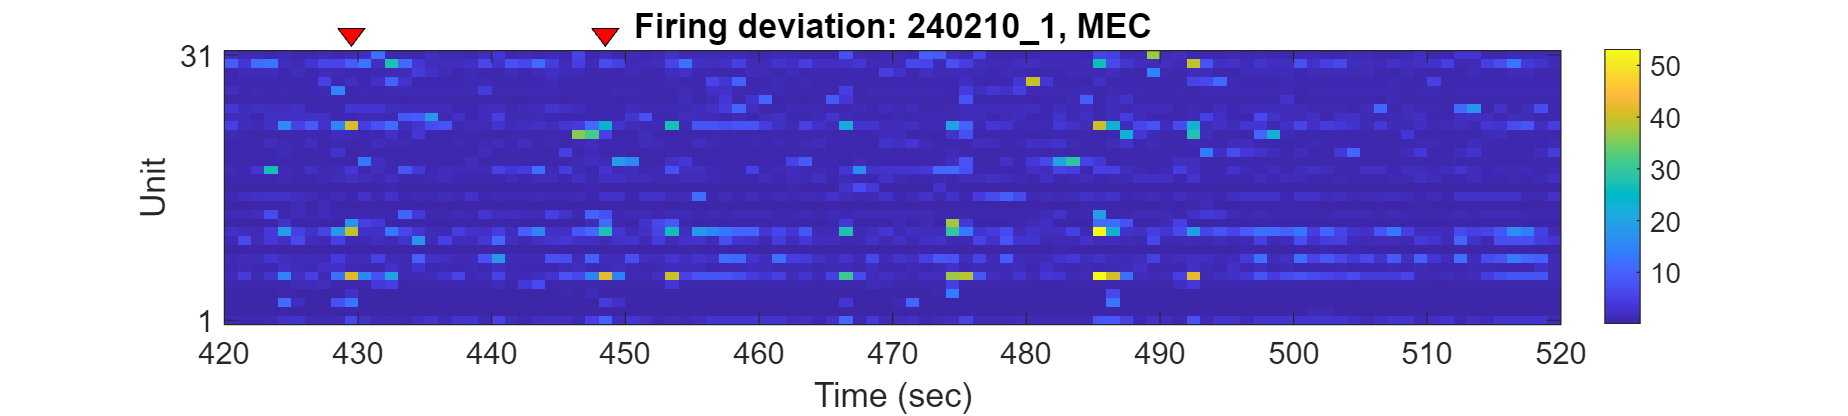

%%% FIGURE
figure
set(gcf,'unit','normalized','position',[0.2 0.3 0.5 0.2])
to_plot = t_bin > 420 & t_bin < 520;
t_fig = t_bin(to_plot); % sec
imagesc(deviation(:,to_plot),'YData',1:n_unit,'XData',t_fig)
yticks([1,n_unit])
% yticklabels(unit_ids)
xlabel('Time (sec)')
ylabel('Unit')
colorbar

% the arrows
x_arrow = [429.5 448.5];
y_arrow = [32 32];
xO = 1;
yO = -2;

patch([x_arrow-xO; x_arrow+xO; x_arrow], ...
    [y_arrow-yO; y_arrow-yO; y_arrow],'r','clipping','off')
% text(x_fd1-0.1, y_fd1, 'Social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)
% text(x_fd2-0.1, y_fd2, 'Non-social', 'fontsize', 14,'HorizontalAlignment','center','Rotation',90)

title('Firing deviation: 240210_1, MEC','interpreter','none')
set(gca,'FontSize',14,'YDir','normal')

It seems like that they keep correlated over time. Look at the cross-correlation for firing deviation and all spikes across the session.

% Unit with correlated firing deviation
corr_th = 10; % p = 1e-5

unit_correlated = find(deviation(:,430)>corr_th);
disp(unit_ids(unit_correlated))
disp(unit_correlated)
unit_corr_pairs = nchoosek(unit_correlated,2); % all pair of correlated units

#### Spike cross-correlation

% Cross-correlation of all spikes
for i = 1:size(unit_corr_pairs,1)
    % unit1 = 6; unit2 = 23;
    unit1 = unit_corr_pairs(i,1);
    unit2 = unit_corr_pairs(i,2);
    spike1 = sptimes_all_usec{unit1}/1e3; % msec
    spike2 = sptimes_all_usec{unit2}/1e3; % msec
    bin = 1; % bin size (msec)
    t_max = 25; % window size (msec)

    [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    fig = figure('visible','off');
    % fig = figure;
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([-0.1 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    % Scale bar
    patch([-20 -10 -10 -20],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    text(-15, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    text(6, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','left')

    FigDir = fullfile(rootdir,'analysis','figure','firing_coupling', ...
        sprintf('Ephys%s_%s',bname_ephys,trjName),'spike_xcorr');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

It looks like the pair of neurons that have synchronized firing deviation may have the tendency to have same inputs or synaptic connection.

% Cross-correlation of firing deviation timings when deviation is high
for i = 1:size(unit_corr_pairs,1)
    unit1 = unit_corr_pairs(i,1);
    unit2 = unit_corr_pairs(i,2);
    spike1 = t_bin(deviation(unit1,:)>corr_th); % sec
    spike2 = t_bin(deviation(unit2,:)>corr_th); % sec
    bin = 1; % bin size (sec)
    t_max = 20; % window size (sec)

    % Compute cross correlation
    [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    %%% FIGURE
    fig = figure('visible','off');
    % fig = figure;
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([-0.1 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    % Scale bar
    patch([-20 -10 -10 -20],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    text(-15, -0.14, '10s', 'fontsize', 14, 'HorizontalAlignment','center')
    text(6, -0.1, '40s (bin=1s)', 'fontsize', 14, 'HorizontalAlignment','left')

    FigDir = fullfile(rootdir,'analysis','figure','firing_coupling', ...
        sprintf('Ephys%s_%s',bname_ephys,trjName),'deviation_xcorr_highDeviation');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

% Cross-correlation of firing deviation timings when deviaiton is low
for i = 1:size(unit_corr_pairs,1)
    unit1 = unit_corr_pairs(i,1);
    unit2 = unit_corr_pairs(i,2);
    spike1 = t_bin(deviation(unit1,:)<corr_th); % sec
    spike2 = t_bin(deviation(unit2,:)<corr_th); % sec
    bin = 1; % bin size (sec)
    t_max = 20; % window size (sec)

    % Compute cross correlation
    [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    %%% FIGURE
    fig = figure('visible','off');
    % fig = figure;
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([0 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    FigDir = fullfile(rootdir,'analysis','figure','firing_coupling', ...
        sprintf('Ephys%s_%s',bname_ephys,trjName),'deviation_xcorr_lowDeviation');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

% Spike cross-correlation when firing deviation is high
corr_th = 2;
for i = 1:size(unit_corr_pairs,1)
    % unit1 = 6; unit2 = 23;
    unit1 = unit_corr_pairs(i,1);
    unit2 = unit_corr_pairs(i,2);
    spike1 = sptimes_all_usec{unit1}/1e6; % sec
    spike1_high_idx = ismember(floor(spike1),t_edge(deviation(unit1,:)>corr_th));
    spike1_high = spike1(spike1_high_idx)*1e3; % msec
    spike1_low = spike1(~spike1_high_idx)*1e3; % msec
    spike2 = sptimes_all_usec{unit2}/1e6; % sec
    spike2_high_idx = ismember(floor(spike2),t_edge(deviation(unit2,:)>corr_th));
    spike2_high = spike2(spike2_high_idx)*1e3; % msec
    spike2_low = spike2(~spike2_high_idx)*1e3; % msec
    bin = 1; % bin size (msec)
    t_max = 25; % window size (msec)

    %%% FIGURE
    fig = figure('visible','off');
    set(fig,'unit','normalized','position',[0.3 0.2 0.3 0.3])

    % fig = figure;
    subplot(1,2,1)
    [xcc,t_xcc] = crosscorr(spike1_high,spike2_high,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    hold on
    line([0 0],[0 1.2],'Color','k')
    hold off
    title(sprintf('Unit%d and %d: High deviation',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([-0.1 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    % Scale bar
    patch([-20 -10 -10 -20],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    text(-15, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    text(6, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','left')


    subplot(1,2,2)
    [xcc,t_xcc] = crosscorr(spike1_low,spike2_low,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);
    
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    hold on
    line([0 0],[0 1.2],'Color','k')
    hold off
    title(sprintf('Unit%d and %d: Low deviation',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([-0.1 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    % Scale bar
    patch([-20 -10 -10 -20],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    text(-15, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    text(6, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','left')

    

    FigDir = fullfile(rootdir,'analysis','figure','firing_coupling', ...
        sprintf('Ephys%s_%s',bname_ephys,trjName),'spike_xcorr_Deviation');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

% Spike cross-correlation when firing deviation is high
for i = 1:size(unit_corr_pairs,1)
    % unit1 = 6; unit2 = 23;
    unit1 = unit_corr_pairs(i,1);
    unit2 = unit_corr_pairs(i,2);
    spike1 = sptimes_all_usec{unit1}/1e6; % sec
    spike1_idx = ismember(floor(spike1),t_edge(deviation(unit1,:)>corr_th));
    spike1 = spike1(spike1_idx)*1e3; % msec
    spike2 = sptimes_all_usec{unit2}/1e6; % sec
    spike2_idx = ismember(floor(spike2),t_edge(deviation(unit2,:)>corr_th));
    spike2 = spike2(spike2_idx)*1e3; % msec
    bin = 1; % bin size (msec)
    t_max = 25; % window size (msec)

    [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    xcc = xcc / max(xcc); % Normalize
    t_xcc = t_xcc(5/bin+1:end-5/bin);

    fig = figure('visible','off');
    % fig = figure;
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    % xticks([-t_max,0,t_max])
    ylim([-0.1 1.2])
    % yticks([])
    set(gca,'XColor','none','YColor','none')

    % Scale bar
    patch([-20 -10 -10 -20],[-0.1 -0.1 -0.07 -0.07],'k','clipping','off')
    text(-15, -0.14, '10ms', 'fontsize', 14, 'HorizontalAlignment','center')
    text(6, -0.1, '50ms (bin=1ms)', 'fontsize', 14, 'HorizontalAlignment','left')

    FigDir = fullfile(rootdir,'analysis','figure','firing_coupling', ...
        sprintf('Ephys%s_%s',bname_ephys,trjName),'spike_xcorr_lowDeviation');
    if isempty(dir(FigDir)); mkdir(FigDir); end
    saveas(fig,fullfile(FigDir,sprintf('Unit%d_%d.png',unit_ids(unit1),unit_ids(unit2))))
    close(fig)
end

% Cross-correlation of firing deviation
spike1 = find(deviation(unit1,:)>10); % spike times (sec)
spike2 = find(deviation(unit2,:)>10); % spike times (sec)
bin = 1; % bin size (sec)
t_max = 10; % window size (sec)

[xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max);
figure
plot(t_xcc, xcc,'k')
xlabel('Time (sec)')
ylabel('Count')

% Cross-correlation of all spikes

figure
set(gcf,'unit','normalized','position',[0 0 1 1])
tiledlayout(4,6,'TileSpacing','tight')
fig_cnt = 1;
while fig_cnt < 24 & fig_cnt <= length(unit_corr_pairs)
    % unit1 = 6; unit2 = 23;
    unit1 = unit_corr_pairs(fig_cnt,1);
    unit2 = unit_corr_pairs(fig_cnt,2);
    spike1 = sptimes_all_usec{unit1}/1e3; % msec
    spike2 = sptimes_all_usec{unit2}/1e3; % msec
    bin = 1; % bin size (msec)
    t_max = 25; % window size (msec)

    
    [xcc,t_xcc] = crosscorr(spike1,spike2,bin,t_max+5);
    xcc = xcc(5/bin+1:end-5/bin);
    % xcc = normalize(xcc,2,'range'); % normalize
    xcc = xcc / max(xcc);
    t_xcc = t_xcc(5/bin+1:end-5/bin);
    % xcc(t_max/bin+1) = 0;
    % figure
    nexttile
    bar(t_xcc, xcc,1,'FaceColor',[150 150 150]/255,'EdgeColor','none')
    title(sprintf('Unit%d and %d',unit_ids(unit1),unit_ids(unit2)))
    xlabel('Time (sec)')
    xticks([-t_max,0,t_max])
    % ylabel('Count')
    % ylim([0 1])
    ylim([0 1.2])
    yticks([])

    fig_cnt = fig_cnt + 1;
end